# **MODEL FALSIFICATION EXAMPLE **

# **FLUX WORKHOP SECTION D **

#### We simulate and compare the behavour of 2 models: 

#### 1) with fixed learning rate 

#### 2) with decaying over trials learning rate 

#### The "true" model used to generate subjects behaviour is the decaying model : it assumes that the subjects update the expected values less by the end of the session. This way, they can "ignore" the occasional bad outcomes. 

#### Our bencmark behaviour would be the proportion of swtiches in the first and the second half of the session 

% Model falsification 
% Script to simulate the behaviour of a model with fixed and decaying learning rate and compare to the "real" data on the probability to switch after a negative prediction error at the beginning and at the end of the session 
% prediction is that subjects stabilize their choices at the end of the
% session -> ignore the irrelevant occasional bad outcomes from a good deck
% The model with the fixed learning rate won't be able to match this
% pattern. 
% NB: we assume the softmax is the same in both models. 


% Vasilisa Skvortsova, 08/2021 for FLUX Workshop Section D 


clear all; 
close all; 
clc;

### PART 1: simulate subject's data using a model with the decaying learning rate: in real life you of course use the true subjects data gathered in the experiment. 

% Generative model 
cfg_data.nsub      = 30;
cfg_data.p         = 0.8; % reward probability  
cfg_data.nblck     = 1; % assuming 1 block 
cfg_data.alphach   = 0.7; % learning rate for the chosen option
cfg_data.eta       = 0.02; % an exponentail decay rate for the learning rate 
cfg_data.tau       = 0.2; % an exponentail decay rate for the learning rate 
cfg_data.alphauch  = 0; % .4; % learning rate for the unchosen option
cfg_data.ntrl      = 300; % assume we have 2 blocks of 60 trials each with 2 reversals within each block (for simplicity in the middle of the block).

true_data  = simulate_data(cfg_data);

Simulating subject 1
Simulating subject 2
Simulating subject 3
Simulating subject 4
Simulating subject 5
Simulating subject 6
Simulating subject 7
Simulating subject 8
Simulating subject 9
Simulating subject 10
Simulating subject 11
Simulating subject 12
Simulating subject 13
Simulating subject 14
Simulating subject 15
Simulating subject 16
Simulating subject 17
Simulating subject 18
Simulating subject 19
Simulating subject 20
Simulating subject 21
Simulating subject 22
Simulating subject 23
Simulating subject 24
Simulating subject 25
Simulating subject 26
Simulating subject 27
Simulating subject 28
Simulating subject 29
Simulating subject 30


### PART 2 Simulate performance of : 1) model with the fixed learning rate 2) model with the decaying learning rate

clc; 

% Model 1 with fixed learning rate 
cfg_m1.nsub      = 30;
cfg_m1.p         = 0.8; % 80 20 
cfg_m1.nblck     = 1; % assuming 1 block 
% fix learning rate for chosen and unchosen option
cfg_m1.alphach   = 0.6; % learning rate for the chosen option
cfg_m1.eta       = 0; % an exponentail decay rate for the learning rate 
cfg_m1.tau       = 0.2; % an exponentail decay rate for the learning rate 
cfg_m1.alphauch  = 0; % .4; % learning rate for the unchosen option
cfg_m1.ntrl      = 300; % assume we have 2 blocks of 60 trials each with 2 reversals within each block (for simplicity in the middle of the block).

m1_data  = simulate_data(cfg_m1);

Simulating subject 1
Simulating subject 2
Simulating subject 3
Simulating subject 4
Simulating subject 5
Simulating subject 6
Simulating subject 7
Simulating subject 8
Simulating subject 9
Simulating subject 10
Simulating subject 11
Simulating subject 12
Simulating subject 13
Simulating subject 14
Simulating subject 15
Simulating subject 16
Simulating subject 17
Simulating subject 18
Simulating subject 19
Simulating subject 20
Simulating subject 21
Simulating subject 22
Simulating subject 23
Simulating subject 24
Simulating subject 25
Simulating subject 26
Simulating subject 27
Simulating subject 28
Simulating subject 29
Simulating subject 30




% Model 2 with decaying learning rate 
cfg_m2.nsub      = 30;
cfg_m2.p         = 0.8; % 80 20 
cfg_m2.nblck     = 1; % assuming 1 block 
% fix learning rate for chosen and unchosen option
cfg_m2.alphach   = 0.8; % learning rate for the chosen option
cfg_m2.eta       = 0.02; % an exponentail decay rate for the learning rate 
cfg_m2.tau       = 0.2; % an exponentail decay rate for the learning rate 
cfg_m2.alphauch  = 0; % .4; % learning rate for the unchosen option
cfg_m2.ntrl      = 300; % assume we have 2 blocks of 60 trials each with 2 reversals within each block (for simplicity in the middle of the block).

m2_data  = simulate_data(cfg_m2);

Simulating subject 1
Simulating subject 2
Simulating subject 3
Simulating subject 4
Simulating subject 5
Simulating subject 6
Simulating subject 7
Simulating subject 8
Simulating subject 9
Simulating subject 10
Simulating subject 11
Simulating subject 12
Simulating subject 13
Simulating subject 14
Simulating subject 15
Simulating subject 16
Simulating subject 17
Simulating subject 18
Simulating subject 19
Simulating subject 20
Simulating subject 21
Simulating subject 22
Simulating subject 23
Simulating subject 24
Simulating subject 25
Simulating subject 26
Simulating subject 27
Simulating subject 28
Simulating subject 29
Simulating subject 30


### PART 3: Compare model performance to true data on the benchmark: Probability to switch after a negative prediction error at the beginning and at the end of the learning session

clc; 
% compute probability to switch as a function of small/large prediction
% error 

switch_data = compute_switch(true_data); 
switch_m1 = compute_switch(m1_data); 
switch_m2 = compute_switch(m2_data);

### PLOT data and model performances

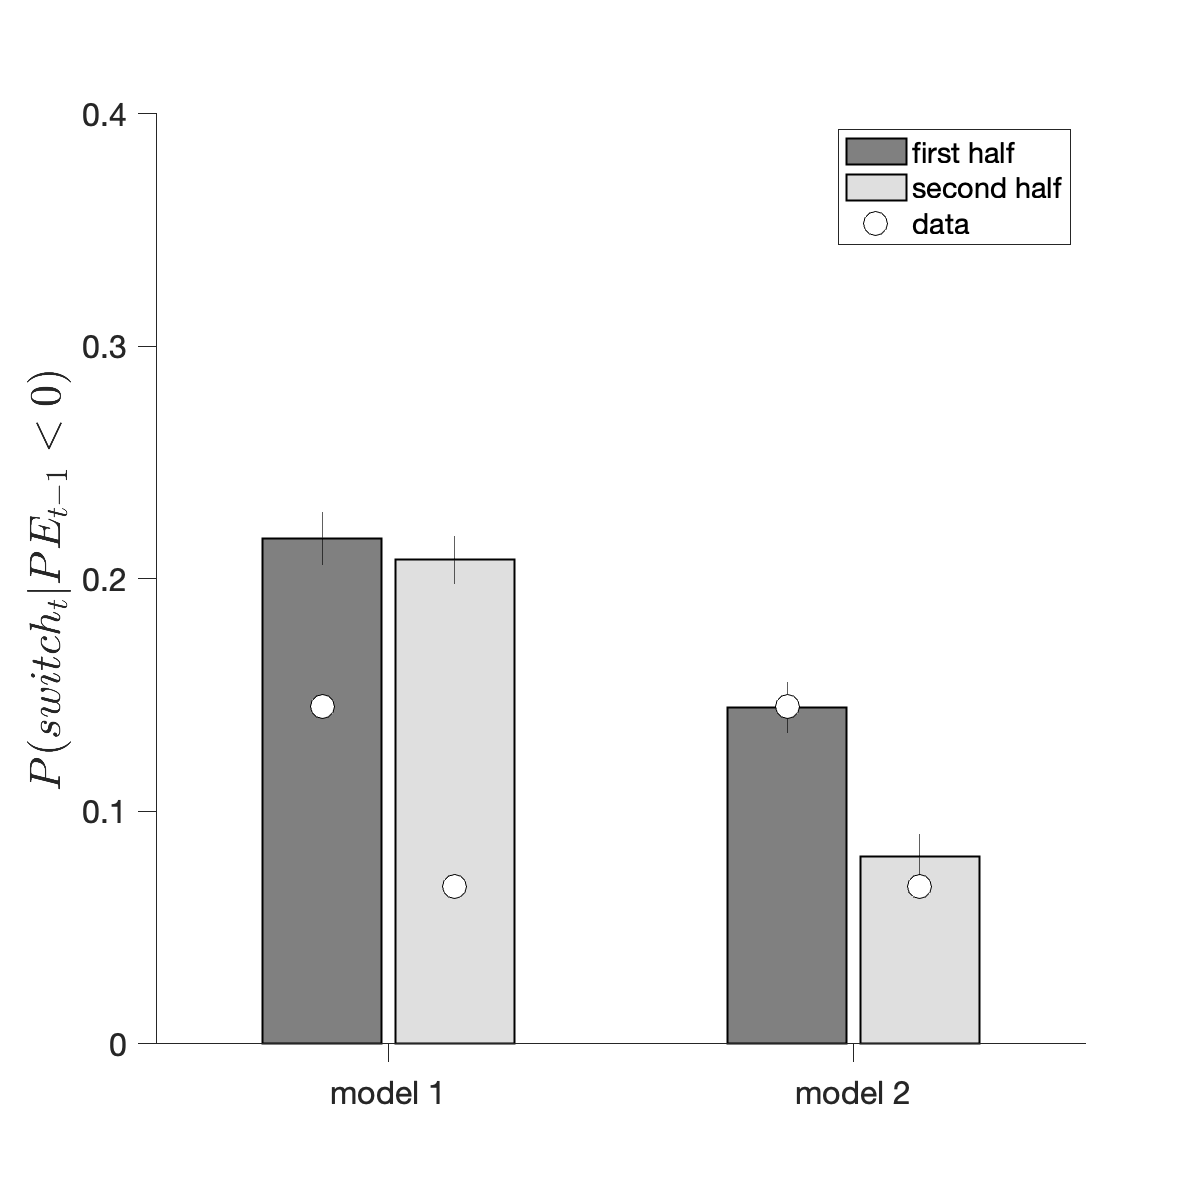

clc; 
close all; 

pbar = 1.0; 
figure('Color','white','Name','Model falsification'); 
set(gcf, 'Position',  [100, 100, 600, 600])


% plot model frequencies for high-scoring subjects
xavg_data = cat(2,mean(switch_data.pe_switch1,1),mean(switch_data.pe_switch2,1));
xstd_data = cat(2,std(switch_data.pe_switch1,1),std(switch_data.pe_switch2,1))./sqrt(cfg_data.nsub);

xavg_data = repmat(xavg_data,2,1); 
xstd_data = repmat(xstd_data,2,1); 


xavg_1 = cat(2,mean(switch_m1.pe_switch1,1),mean(switch_m1.pe_switch2,1));
xstd_1 = cat(2,std(switch_m1.pe_switch1,1),std(switch_m1.pe_switch2,1))./sqrt(cfg_m1.nsub);
xavg_2 = cat(2,mean(switch_m2.pe_switch1,1),mean(switch_m2.pe_switch2,1));
xstd_2 = cat(2,std(switch_m2.pe_switch1,1),std(switch_m2.pe_switch2,1))./sqrt(cfg_m2.nsub);

xavg = cat(1,xavg_1,xavg_2); 
xstd = cat(1,xstd_1,xstd_2); 


ngrp = size(xavg,1);
nbar = size(xavg,2);
wbar = 0.9;
wgrp = min(wbar,nbar/(nbar+1.5));

subplot(1,1,1); 
hold on
h  = bar(xavg(:,:,1),0.9,'LineWidth',1);

   
set(h(1),'FaceColor',[0.5,0.5,0.5]);
set(h(2),'FaceColor',[0.875,0.875,0.875]);


for ibar = 1:nbar
    for igrp = 1:ngrp
        x = igrp-wgrp/2+(2*ibar-1)*wgrp/nbar/2;
        plot(x*[1,1],xavg(igrp,ibar,1)+xstd(igrp,ibar,1)*[-1,+1],'k-','MarkerSize',12,'MarkerFaceColor',[1,1,1]);
        
       plot(x*[1,1],xavg_data(igrp,ibar,1),'ko','MarkerSize',12,'MarkerFaceColor',[1,1,1]);
   
    end
    
        
end


legend('first half','second half','','data'); 

xlim([0.5,2.5]);
ylim([0,0.4]);
set(gca,'Layer','top','Box','off','PlotBoxAspectRatio',[pbar,1,1]);
set(gca,'TickDir','out','TickLength',[1,1]*0.02/max(pbar,1));
set(gca,'FontName','Helvetica','FontSize',16);
set(gca,'XTick',[1,2],'XTickLabel',{'model 1','model 2'});
set(gca,'YTick',0:0.1:0.4);
ylabel('$P(switch_{t}| PE_{t-1} < 0)$','Interpreter','Latex','FontSize',22);

drawnow;

## === Additional functions ====== %%

function out_switch = compute_switch(data)

nsub = size(data,2); 
ntrl = numel(data(1).pe); 

out_switch = zeros(nsub,4); 
for i_s = 1:nsub
    
    % split the data into 2 parts 
    
    p = data(i_s).pe; 
    r = data(i_s).resp; 
    
    pe_idx = find(p<0); 
    
    % Compute the proportion of switches in part 1 and part 2: 
    
    meanswitch_1 = mean(abs(diff(r(1:ntrl/2)))); 
    meanswitch_2 = mean(abs(diff(r(ntrl/2+1:end)))); 
    
    % switch after a negative pe 
    count_switch1 = 0;
    count_switch2 = 0;
    
    for ii = 1:length(pe_idx)
        
        if pe_idx(ii) < ntrl
            
        if r(pe_idx(ii)+1)~=r(pe_idx(ii))
            if pe_idx(ii) <=ntrl/2 % if it was a switch on the next trial
                count_switch1 = count_switch1 + 1;
            else
                count_switch2 = count_switch2 + 1;
                
            end
            
        end
        else
            continue
        end
    end
    
    switch_1 =  mean(count_switch1)/sum(pe_idx<=ntrl/2); 
    switch_2 =  mean(count_switch2)/sum(pe_idx>ntrl/2); 
  
    
    out_switch(i_s,1)  = switch_1; 
    out_switch(i_s,2)  = switch_2; 
    out_switch(i_s,3)  = meanswitch_1; 
    out_switch(i_s,4)  = meanswitch_2; 
    
end

  out_switch = array2table(out_switch,'VariableNames',{'pe_switch1','pe_switch2','meanswitch1','meanswitch2'}); 

end


function out = simulate_data(cfg)

if ~isfield(cfg,'p')
    fprintf('No reward probability specified, assume probability of reward is 0.75\n')
    p = 0.75;
else
    p = cfg.p;
end


if ~isfield(cfg,'tau')
    fprintf('No value for softmax, assuming tau = 0.1\n')
    tau = 0.1;
else
    tau  = cfg.tau;
end


if ~isfield(cfg,'alphach')
    fprintf('No value for learning rate chosen, assuming learnng rate chosen = 0.5\n')
    alphach = 0.5;
else
    alphach  = cfg.alphach;
end


if ~isfield(cfg,'alphauch')
    fprintf('No value for learning rate unchosen, assuming no update for the unchosen option\n')
    alphauch = 0;
else
    alphauch  = cfg.alphauch;
end


if ~isfield(cfg,'eta')
    fprintf('No value for decaying learning rate assume learning rate is fixed\n')
    eta = 0;
else
    eta  = cfg.eta;
end


if ~isfield(cfg,'nsub')
    fprintf('Assuming 1 subject\n')
    nsub  = 1;
else
    nsub  = cfg.nsub;
end


if ~isfield(cfg,'ntrl')
    fprintf('Assuming 120 trials\n')
    
    ntrl  = 120;
else
    ntrl  = cfg.ntrl;
end


if ~isfield(cfg,'nblck')
    fprintf('Assuming 2 blocks\n')
    
    nblck  = 2;
else
    nblck  = cfg.nblck;
end


ntrl_blck = ntrl/nblck;



for i_s = 1:nsub
    
    fprintf('Simulating subject %d\n',i_s)
    % create binary rewards with reward probability p
    rew1 = [];
    rew2 = [];
    
    for i_b = 1:nblck
        
        
        r1                  = zeros(1,ntrl);
        r2                  = zeros(1,ntrl); 
        
        r1(1:floor(ntrl*p))     = 1; 
        r1(1:floor(ntrl*(1-p))) = 1; 
        
        r1 = r1(randperm(length(r1))); 
        r2 = r2(randperm(length(r2))); 
        
        
        if mod(i_b,2) == 1
            rew1 = cat(2,rew1,r1);
            rew2 = cat(2,rew2,r2);
            
        else
            rew1 = cat(2,rew1,r2);
            rew2 = cat(2,rew2,r1);
        end
    end
    
    rewards = cat(1,rew1,rew2);
    
    [resp,per] = get_simulate(rewards,alphach,alphauch,tau,eta); 
    
    out(i_s).resp    = resp; 
    out(i_s).rewards = rewards; 
    out(i_s).pe      = per; 
    
end
end

% simulate agent with specific learning paramaters 

function [resp,per] = get_simulate(rewards,alphach,alphauch,tau,eta)

    % compute Q-values
    ntrl    = size(rewards,2); 
    q       = nan(ntrl,2);
    resp    = nan(ntrl,1); 
    
    q(1,:) = 0.5;
    vm     = [0.5,0.5]; % cached value for each bandit
    
    % first choice is random 
    resp(1) = double(rand>0.5)+1; % between 1 and 2 
    
    
    alpha_decay    = nan(1,ntrl); 
    alpha_decay(1) = alphach; 
    per             = nan(1,ntrl); 
    per(1)          = 0; 
    
        
    for itrl = 2:ntrl
        
        r = resp(itrl-1);
        
        
        vm(r)   = rewards(r,itrl-1); % update cached value for chosen bandit
        vm(3-r) = 1 - vm(r); % assume anticorrelation
        
        % compute the the decaying learning rate 
        alpha_decay(itrl) = alphach/(1+eta*(itrl-1));  
        
        % update the Q-values
        per(itrl)    = vm(r)-q(itrl-1,r); 
        
        q(itrl,r)   = q(itrl-1,r)+alpha_decay(itrl)*(vm(r)-q(itrl-1,r));
       
        q(itrl,3-r) = q(itrl-1,3-r)+alphauch*(vm(3-r)-q(itrl-1,3-r)); % alpha unchosen is always 0 in this example 
        
        
        deltaQ = q(itrl,1) - q(itrl,2);    % difference in Q values between options 1 and option 2 
        proba  = 1./(1+exp(-deltaQ/tau));  % softmax for 2 options 
        
        resp(itrl) = (1-sampleFromArbitraryP([proba,1-proba],[1,0]',1))+1; 
        
    end
    
    
%     figure('Color','white');
%     plot(1:ntrl, alpha_decay,'LineWidth',2.0,'Color','r');
%     ylabel('decaying learning rate ${\alpha}$','Interpreter','Latex','FontSize',20);
%     xlabel('Trials','FontSize',18);
%     set(gca,'Layer','top','Box','off');
%     set(gca,'TickDir','out','TickLength',[1,1]*0.02);
%     set(gca,'FontName','Helvetica','FontSize',16);

    
   
end